# E3DSB miniprojekt 2 - frekvensanalyse

## Indledning

Der vil blive anvendt diskret Fouriertransformation (DFT) til at analysere frekvensindholdet i følgende signaler:

Vindmøllestøj og musiknumret "Spit Out The Bone" med Metallica. Der vil blive anvendt Matlab til at håndtere disse analyser.

clc; clear all; close all;
[metallica, fs_m] = audioread("C:\Users\Bluns\OneDrive\Skrivebord\E3DSB\Metallica_Spit_Out_The_Bone.m4a");
% vindmøllestøj 20 sekunder fundet på You Tube (de første 20 sekunder)
% https://www.youtube.com/watch?v=Mk5zMxYVca0&fbclid=IwAR1xhwol-65W8nkN6jYkoNhX2obIx3ou__Iqf-CeBdmWcqXN33GCcK_7bn0
[vind,fs_v] = audioread("C:\Users\Bluns\OneDrive\Skrivebord\E3DSB\Wind-turbine-sound-high-quality-audio.mp3");

% der anvendes 20 sekunder af lydfilen
metallica_seg = metallica(1:44100*20);
% Længden findes (total antal af frekvensbins)
N_m = length(metallica_seg);
N_v = length(vind);
% finder samplingfrekvensen 
T = table(fs_m,fs_v)

T = 1×2 table
    fs_m     fs_v 
    _____    _____

    44100    44100



% Frekvensopløsningen (Hz)
df_m = fs_m/N_m;
df_v = fs_v/N_v;

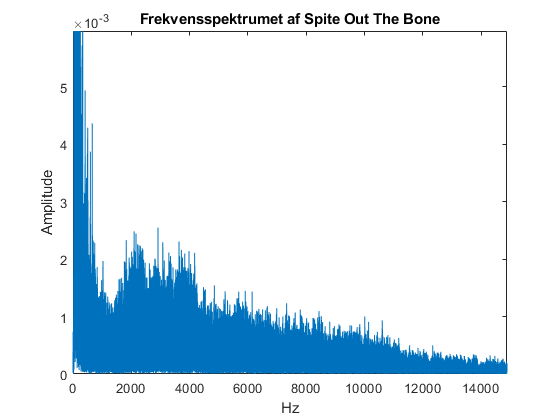

% fft metallica_seg
fft_m = fft(metallica_seg);
% Vi plotter halvdelen af det 882000 (dvs 441000)
vektor_m =df_m*(0:441000-1);

% plotter den venstre side af nyquist frekvensen
plot(vektor_m,(abs(fft_m(1:N_m/2)))*2/N_m)
title("Frekvensspektrumet af Spite Out The Bone")
xlabel("Hz")
ylabel("Amplitude")

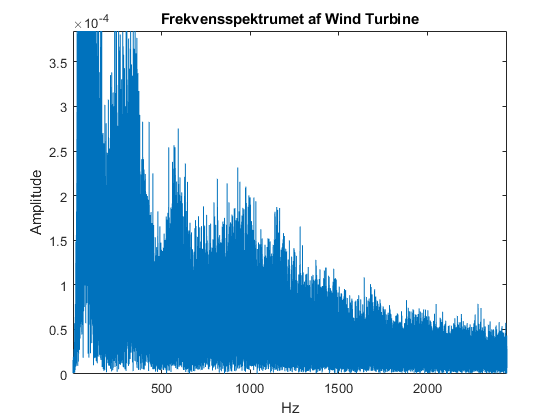

% fft metallica_seg
fft_v = fft(vind);
% Vi plotter halvdelen af det 883056 (dvs 441528)
vektor_v =df_v*(0:441528-1);

% plotter den venstre side af nyquist frekvensen
plot(vektor_v,(abs(fft_v(1:N_v/2)))*2/N_v)
title("Frekvensspektrumet af Wind Turbine")
xlabel("Hz")
ylabel("Amplitude")

**Sammenligning af de to frekvenser**

Der bemærkes at der kunne forfindes lavfrekvente energi ved vindmøllestøjen, hvorimod der også forkommer energi ved større frekvenser og dermed en større spredning ved Metallicas musik nummer end ved vindmøllestøjen.

Det bemærkes at filer som mp3 og mp4 er lyden komprimeret så der ikke forfindes frekvenser der ligger udenfor det hørebar spektrum ( ca 20 - 20000 Hz, dog høre bedst i intervallet 100 - 5000Hz)